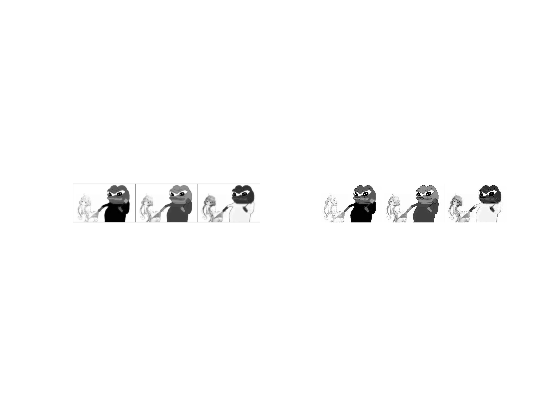

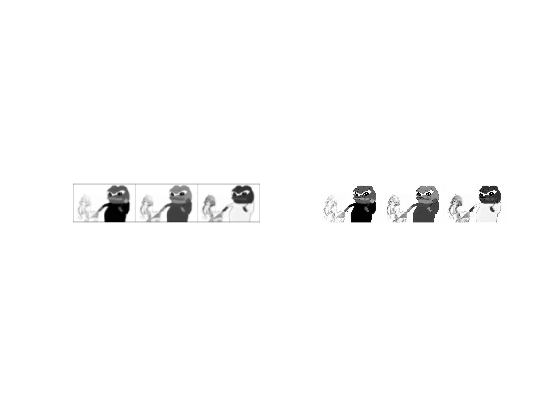

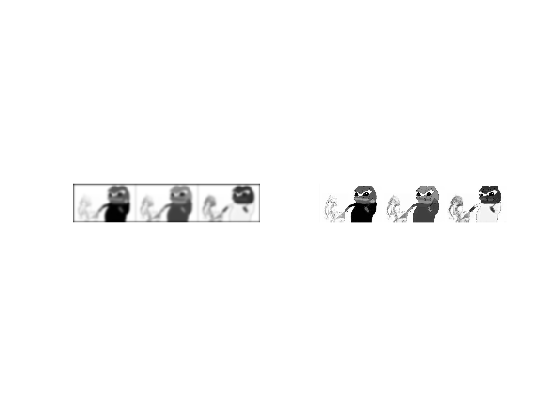

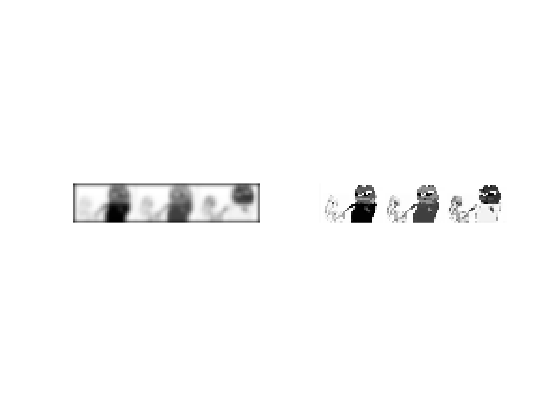

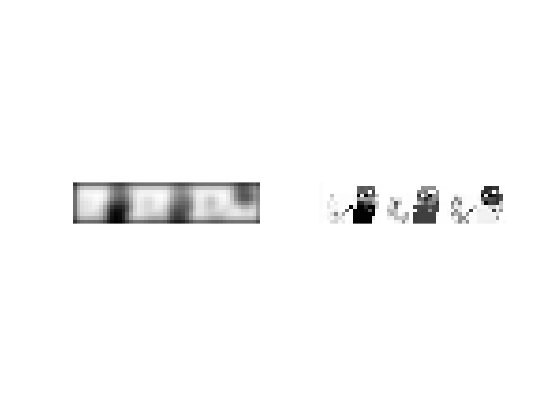

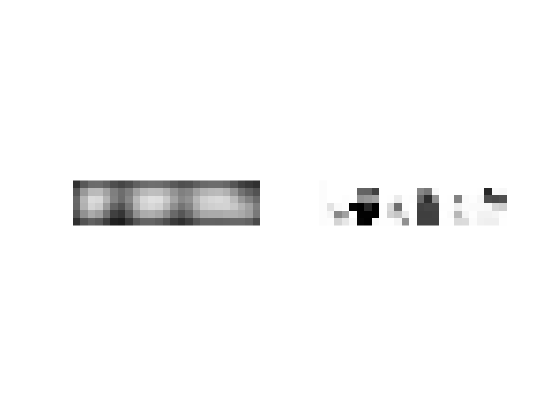

mI = im2double(imread('https://steamuserimages-a.akamaihd.net/ugc/938307470432977722/A122C443FF1DF7A74675F710CDBA6E27D4258809/'));
mG = mI;

sigma = 2;
L = 2 * ceil(5/2 * sigma) + 1;
mH_Gaus = fspecial('gaussian', L, sigma);
n = 6;

for x= 1:n
    mI = mI(1:2:end, 1:2:end);
    mG = imfilter(mG, mH_Gaus);
    mG = mG(1:2:end, 1:2:end);
    
    figure,
    subplot(122), imshow(mI)
    subplot(121), imshow(mG)
end